clear; close all; clc

% 22
x = [1, 4, 2, 3, 5, 3, 3, 4, 5, 7, 6, 9];
h1 = [1, 1];
h2 = [1, 2, 1];
h3 = [1/2, 1/2];
h4 = [1/4, 1/2, 1/4];
h5 = [1/4, -1/2, 1/4];
h6 = [1/2, -1/2];
y1 = conv(x,h1)

y1 =      1     5     6     5     8     8     6     7     9    12    13    15     9


y2 = conv(x,h2)

y2 =      1     6    11    11    13    16    14    13    16    21    25    28    24     9


y3 = conv(x,h3)

y3 =     0.5000    2.5000    3.0000    2.5000    4.0000    4.0000    3.0000    3.5000    4.5000    6.0000    6.5000    7.5000    4.5000


y4 = conv(x,h4)

y4 =     0.2500    1.5000    2.7500    2.7500    3.2500    4.0000    3.5000    3.2500    4.0000    5.2500    6.2500    7.0000    6.0000    2.2500


y5 = conv(x,h5)

y5 =     0.2500    0.5000   -1.2500    0.7500    0.2500   -1.0000    0.5000    0.2500         0    0.2500   -0.7500    1.0000   -3.0000    2.2500


y6 = conv(x, h6)

y6 =     0.5000    1.5000   -1.0000    0.5000    1.0000   -1.0000         0    0.5000    0.5000    1.0000   -0.5000    1.5000   -4.5000


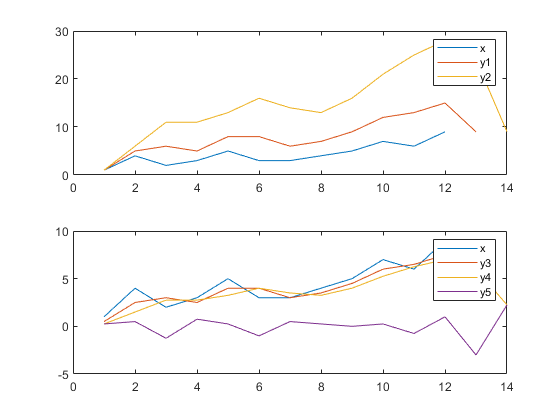

figure
subplot(2, 1, 1)
plot(x)
hold on
plot(y1)
plot(y2)
hold off
legend('x', 'y1', 'y2')

subplot(2,1,2)
plot(x)
hold on
plot(y3)
plot(y4)
plot(y5)
hold off
legend('x', 'y3', 'y4', 'y5')

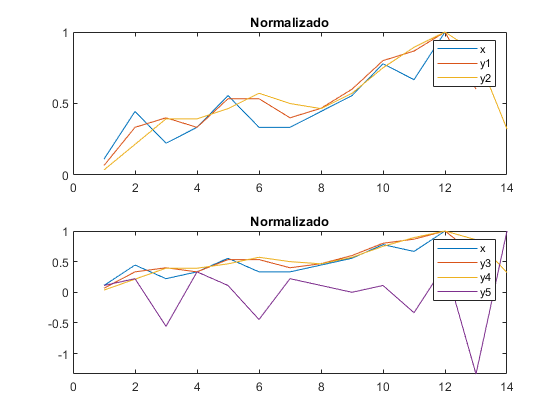

figure
subplot(2, 1, 1)
plot(x/max(x))
hold on
plot(y1/max(y1))
plot(y2/max(y2))
hold off
legend('x', 'y1', 'y2')
title('Normalizado')

subplot(2,1,2)
plot(x/max(x))
hold on
plot(y3/max(y3))
plot(y4/max(y4))
plot(y5/max(y5))
hold off
legend('x', 'y3', 'y4', 'y5')
title('Normalizado')

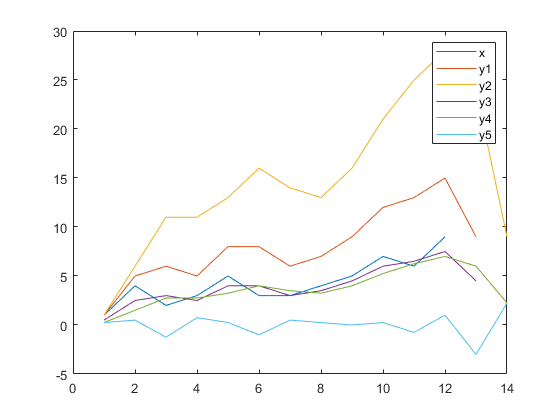

figure
plot(x)
hold on
plot(y1)
plot(y2)
plot(y3)
plot(y4)
plot(y5)
hold off
legend('x', 'y1', 'y2','y3', 'y4', 'y5')

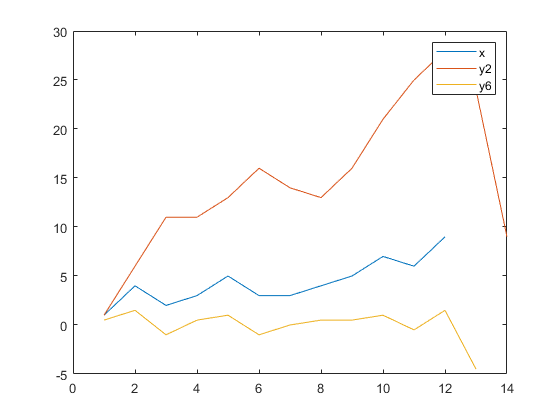

figure
plot(x)
hold on
plot(y2)
plot(y6)
legend('x', 'y2', 'y6')